**Laboratorium 10 – Filtracja Sygnałów, filtry FIR**

**Jakub Szczypek nr 405912**

**grupa 5 WEAIiIB air**

Zadanie 1

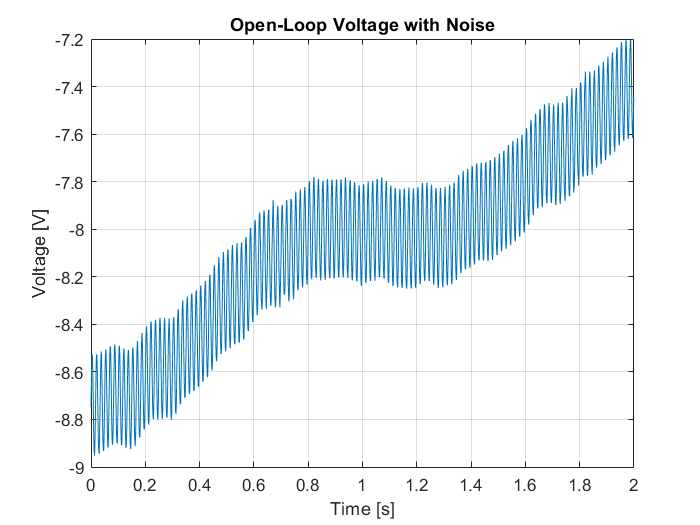

figure
load openloop60hertz, openLoop=openLoopVoltage;
Fs=1000;
t=(0:length(openLoop)-1)/Fs;
plot(t, openLoop); box on; grid on;
ylabel 'Voltage [V]', xlabel 'Time [s]'
title 'Open-Loop Voltage with Noise' 

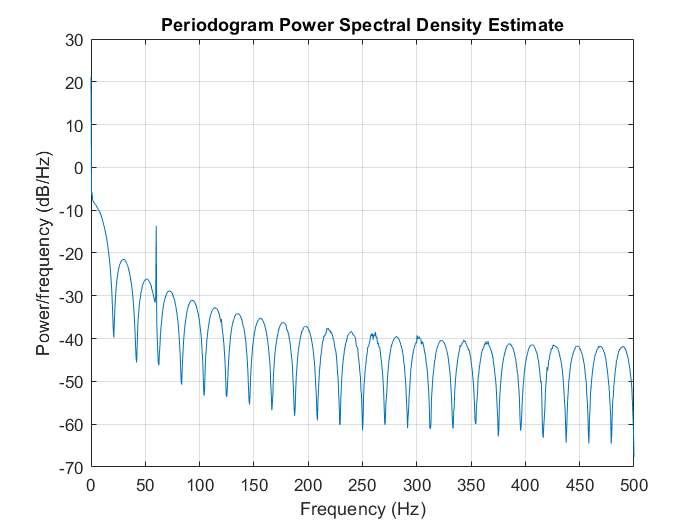


%% Power spectrum - Moc
%% na ok 60 Hz widzimy zaklocenie 

figure;
periodogram(openLoop, [], [], Fs);

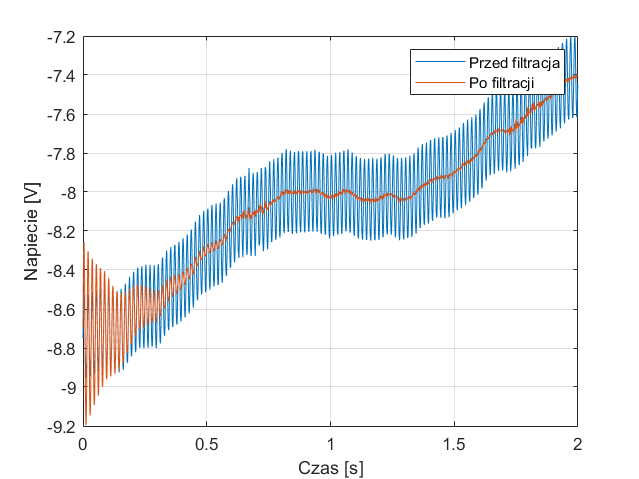


%% Projektujemy filtr

filtCoeff= designfilt('bandstopiir', 'FilterOrder', 2,...
'HalfPowerFrequency1', 59, 'HalfPowerFrequency2', 61, ...
'SampleRate', Fs);

%% Wykres filtru

fvtool(filtCoeff)
noiseFreeSignal= filter(filtCoeff, openLoop);

%% sprawadzamy wynik w dziedzinie czasu

close all;
figure;
plot (t, openLoop, t, noiseFreeSignal); grid on;
legend('Przed filtracja', 'Po filtracji');
ylabel 'Napiecie [V]', xlabel 'Czas [s]'

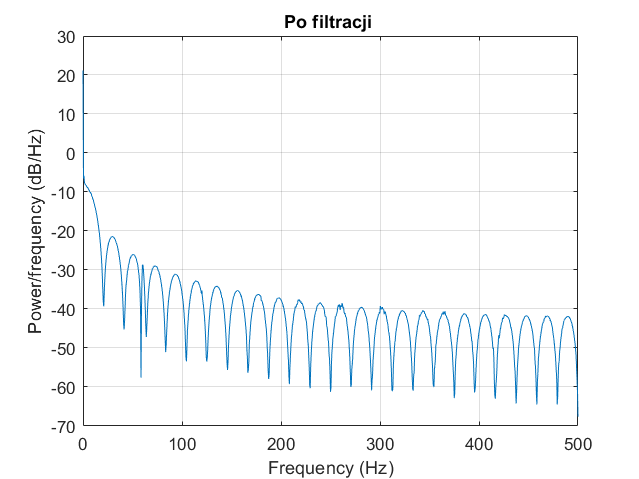


%% sprawdzamy wynik w dziedzinie częstotliwości

figure;
periodogram(noiseFreeSignal, [], [], Fs);
title('Po filtracji ');

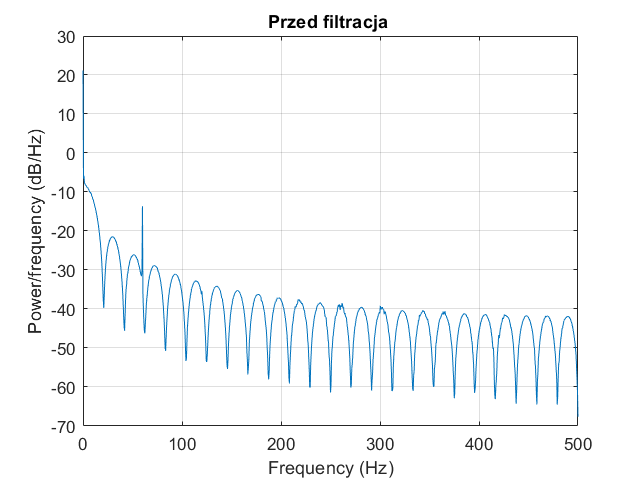

figure;
periodogram(openLoop, [], [], Fs);
title('Przed filtracja ');

Zadanie 2

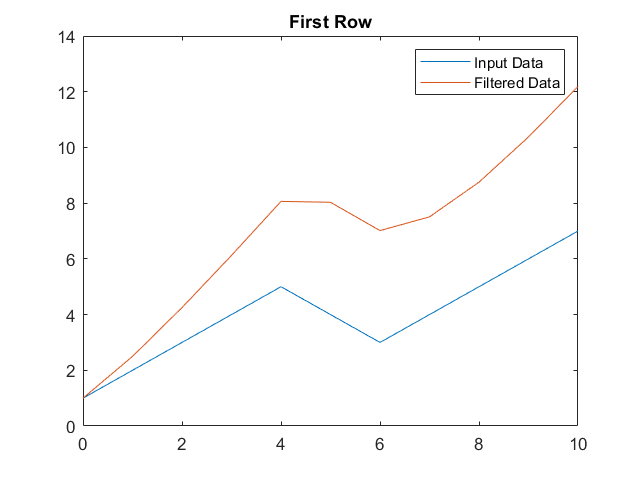

clear all, close all
x= [1,2,3,4,5,4,3,4,5,6,7];
b = 1;
a = [1 -0.5];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data')
title('First Row')

Zadanie 3

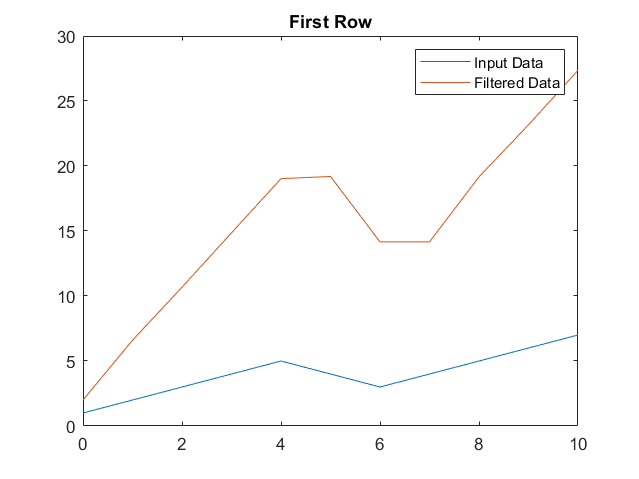

clear all, close all
x= [1,2,3,4,5,4,3,4,5,6,7];
b = [2, 3];
a = [1 0.2];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data')
title('First Row')

Zadanie 4

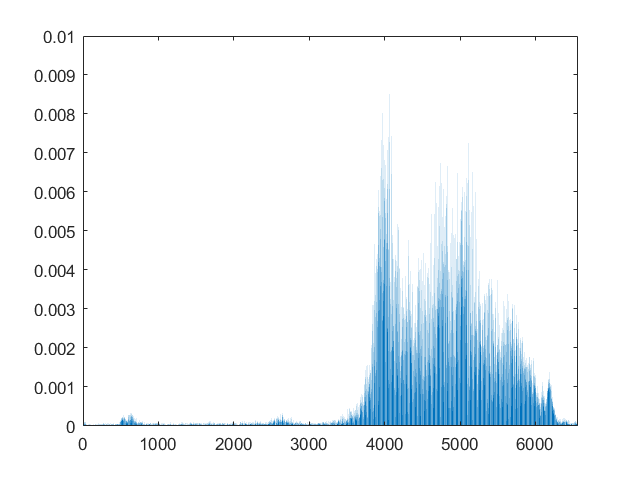

clear all, close all
b = 1;
a = [1 -0.5];

x = rand(2, 15);
y = filter(b, a, x, [], 2);

load chirp;
Fs= 1000;
t = (0:length(y)-1)/Fs; %1.6 sekundy

xfft = abs(fft(y));
xfft = xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

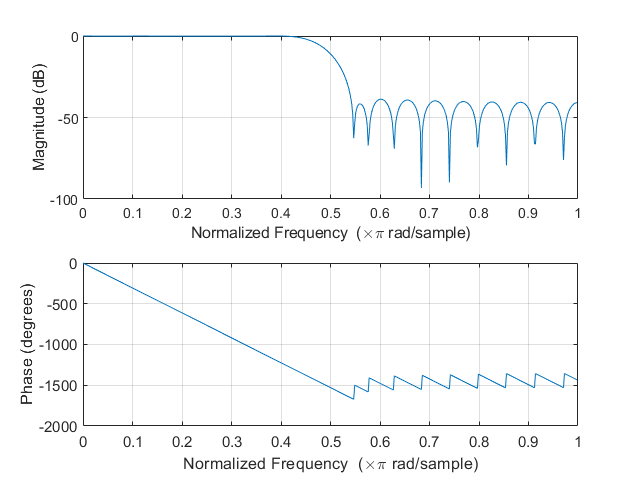


bhi = fir1(34, 0.48, 'low', chebwin(35, 30));
freqz(bhi,1)

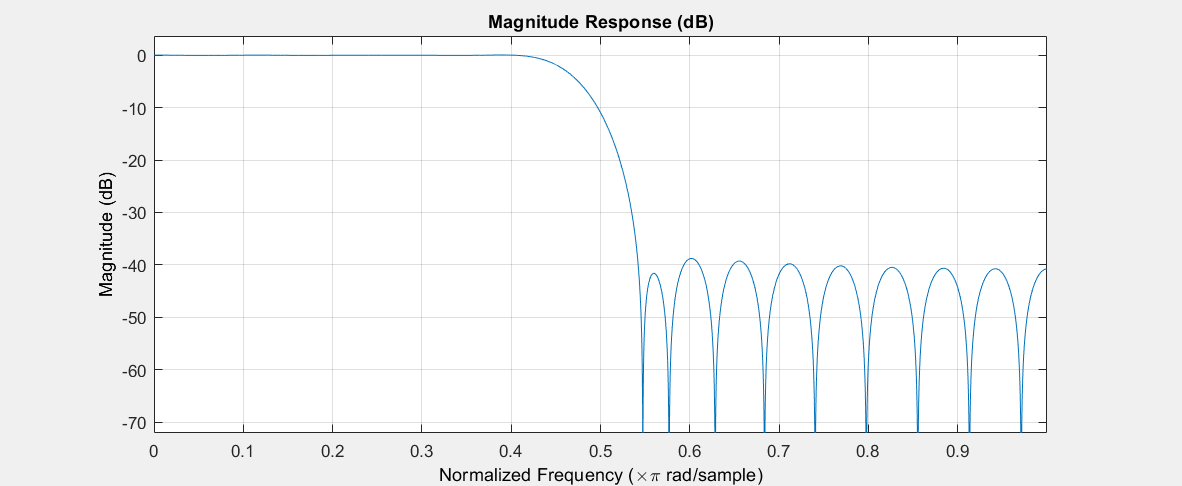

fvtool(bhi)

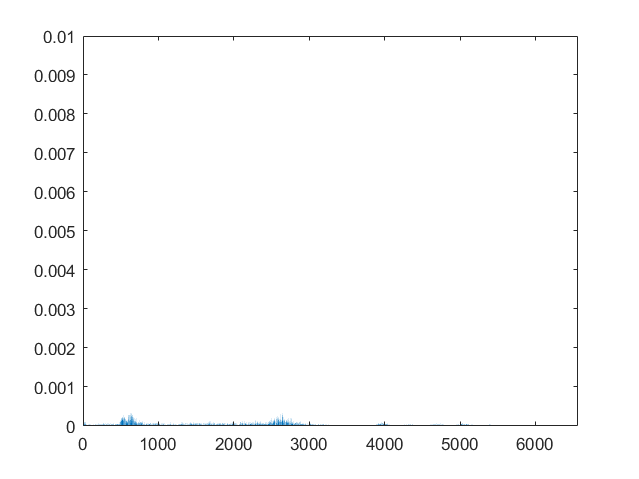

outhi=filter(bhi,1,y);

xfft=abs(fft(outhi));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

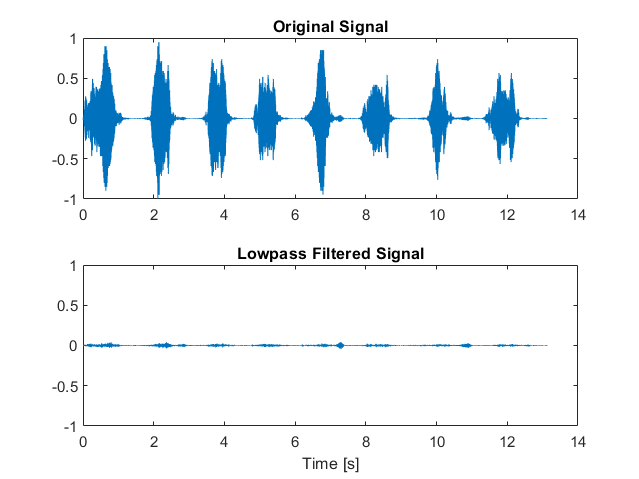


subplot(2,1,1)
plot(t,y);
title('Original Signal');
ys=ylim;

subplot(2,1,2)
plot(t, outhi)
title('Lowpass Filtered Signal');
xlabel('Time [s]');
ylim(ys);

Zadanie 5

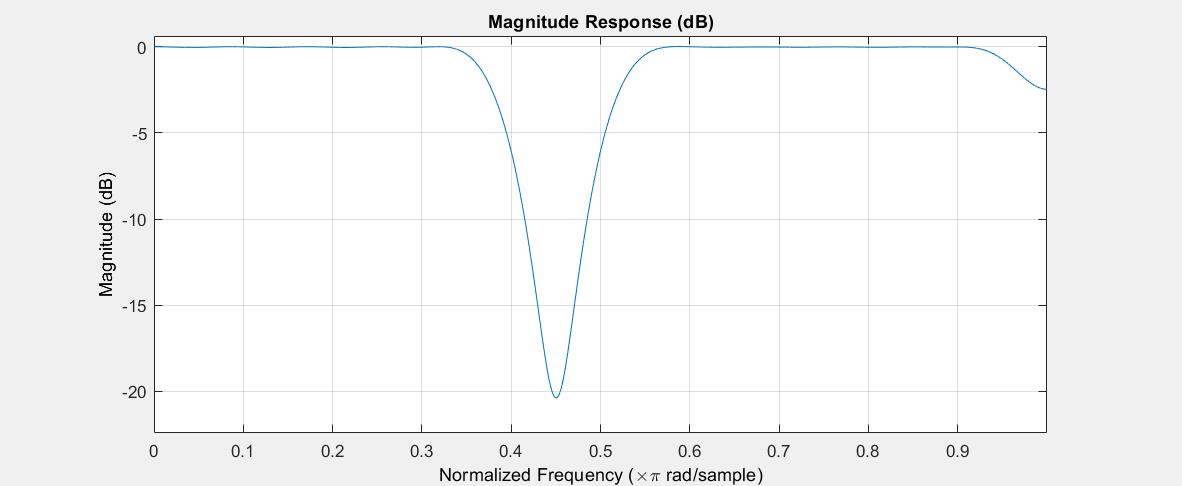

clear all, close all
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord,[low bnd], 'DC-1');
fvtool(bM)

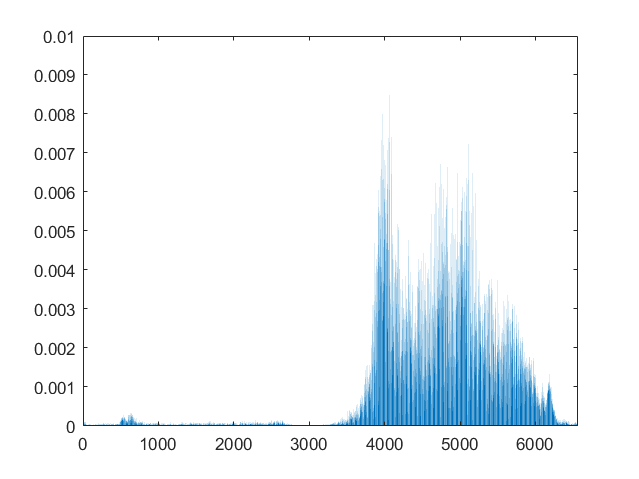

outF = filter(bM,1,y);
xfft=abs(fft(outF));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

Zadanie 6

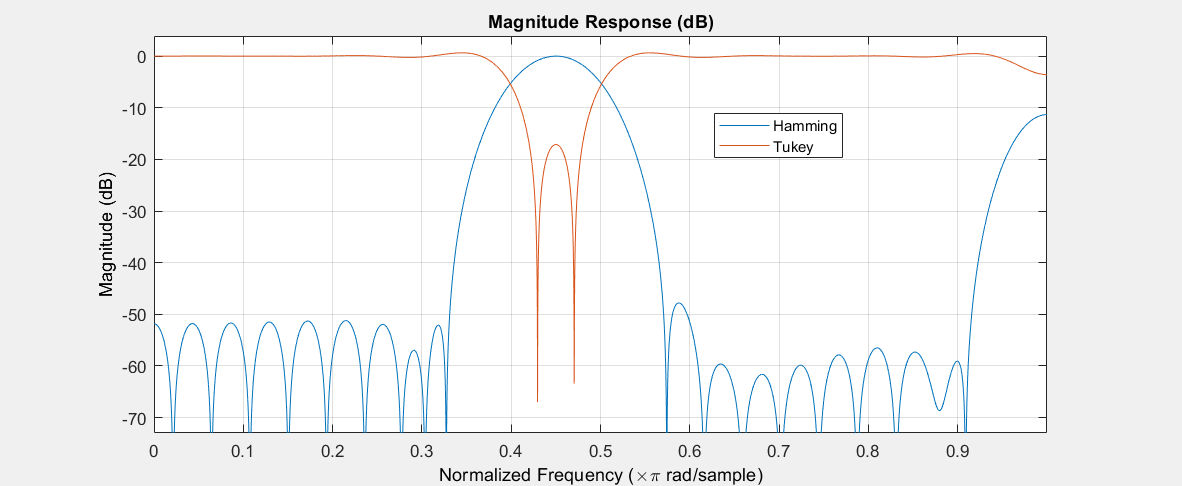

clear all, close all
load chirp;
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord,[low bnd]);
tW = fir1(ord,[low bnd],'DC-1',tukeywin(ord+1));
hfvt = fvtool(bM,1,tW,1);
legend(hfvt,'Hamming','Tukey')

Zadanie 7

x1 = przekladnia20;
x2 = przekladnia21;
x3 = przekladnia23;
x4 = przekladnia24;
x5 = wiatrak20;
x6 = wiatrak21;
x7 = wiatrak23;
x8 = wiatrak24;

% Dla  x1
max_x1 = max(abs(x1));
x1 = x1 / max_x1;
xfft1 = abs(fft(x1));
xfft1 = xfft1 / 44100;
xfft1(1:500) = 0;
xfft1(1001:44100) = 0;

%zapisywanie do pliku FFT_filtracja_wiatrak20.txt
fid = fopen('FFT_filtracja_przekladnia20.txt','w+t','n');
fprintf(fid,'%f\n',xfft1(1:22050));
fclose(fid)

ans = 0


% Dla x2
max_x2 = max(abs(x2));
x2 = x2 / max_x2;
xfft2 = abs(fft(x2));
xfft2 = xfft2 / 44100;
xfft2(1:500) = 0;
xfft2(1001:44100) = 0;

%zapisywanie do pliku FFT_filtracja_wiatrak20.txt
fid = fopen('FFT_filtracja_przekladnia21.txt','w+t','n');
fprintf(fid,'%f\n',xfft2(1:22050));
fclose(fid)

ans = 0


% Dla x3
max_x3 = max(abs(x3));
x3 = x3 / max_x3;
xfft3 = abs(fft(x3));
xfft3 = xfft3 / 44100;
xfft3(1:500) = 0;
xfft3(1001:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_przekladnia23.txt','w+t','n');
fprintf(fid,'%f\n',xfft3(1:22050));
fclose(fid)

ans = 0


% Dla x4
max_x4 = max(abs(x4));
x4 = x4 / max_x4;
xfft4 = abs(fft(x4));
xfft4 = xfft4 / 44100;
xfft4(1:500) = 0;
xfft4(1001:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_przekladnia24.txt','w+t','n');
fprintf(fid,'%f\n',xfft4(1:22050));
fclose(fid)

ans = 0


% Dla x5
max_x5= max(abs(x5));
x5 = x5 / max_x5;
xfft5 = abs(fft(x5));
xfft5 = xfft5 / 44100;
xfft5(1:500) = 0;
xfft5(1001:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_wiatrak20.txt','w+t','n');
fprintf(fid,'%f\n',xfft5(1:22050));
fclose(fid)

ans = 0


% Dla x6
max_x6= max(abs(x6));
x6 = x6 / max_x6;
xfft6 = abs(fft(x6));
xfft6 = xfft6 / 44100;
xfft6(1:500) = 0;
xfft6(1001:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_wiatrak21.txt','w+t','n');
fprintf(fid,'%f\n',xfft6(1:22050));
fclose(fid)

ans = 0


% Dla x7
max_x7= max(abs(x7));
x7 = x7 / max_x7;
xfft7 = abs(fft(x7));
xfft7 = xfft7 / 44100;
xfft7(1:500) = 0;
xfft7(1001:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_wiatrak23.txt','w+t','n');
fprintf(fid,'%f\n',xfft7(1:22050));
fclose(fid)

ans = 0


% Dla x8
max_x8= max(abs(x8));
x8 = x8 / max_x8;
xfft8 = abs(fft(x8));
xfft8 = xfft8 / 44100;
xfft8(1:500) = 0;
xfft8(1001:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_wiatrak24.txt','w+t','n');
fprintf(fid,'%f\n',xfft8(1:22050));
fclose(fid)

ans = 0


load FFT_filtracja_wiatrak20.txt
load FFT_filtracja_wiatrak21.txt
load FFT_filtracja_przekladnia20.txt
load FFT_filtracja_przekladnia21.txt
load FFT_filtracja_wiatrak23.txt
load FFT_filtracja_wiatrak24.txt
load FFT_filtracja_przekladnia23.txt
load FFT_filtracja_przekladnia24.txt 

D1=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak20))

D1 = 0.6032

D2=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak21))

D2 = 0.5950

D3=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia20))

D3 = 0.6336

D4=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia21))

D4 = 0.6120

D5=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_wiatrak20))

D5 = 0.6967

D6=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_wiatrak21))

D6 = 0.5745

D7=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_przekladnia20))

D7 = 0.6558

D8=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_przekladnia21))

D8 = 0.6552

D9=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_wiatrak20))

D9 = 0.6296

D10=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_wiatrak21))

D10 = 0.6506

D11=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_przekladnia20))

D11 = 0.4742

D12=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_przekladnia21))

D12 = 0.4399

D13=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_wiatrak20))

D13 = 0.6608

D14=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_wiatrak21))

D14 = 0.6161

D15=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_przekladnia20))

D15 = 0.4408

D16=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_przekladnia21))

D16 = 0.4834

D17=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak20))

D17 = 0.6032

D18=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak21))

D18 = 0.5950

D19=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia20))

D19 = 0.6336

D20=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia21))

D20 = 0.6120

Zadanie 8

% Dla  x1
max_x1 = max(abs(x1));
x1 = x1 / max_x1;
xfft1 = abs(fft(x1));
xfft1 = xfft1 / 44100;
xfft1(1:100) = 0;
xfft1(1501:44100) = 0;

%zapisywanie do pliku FFT_filtracja_wiatrak20.txt
fid = fopen('FFT_filtracja_przekladnia20.txt','w+t','n');
fprintf(fid,'%f\n',xfft1(1:22050));
fclose(fid)

ans = 0


% Dla x2
max_x2 = max(abs(x2));
x2 = x2 / max_x2;
xfft2 = abs(fft(x2));
xfft2 = xfft2 / 44100;
xfft2(1:100) = 0;
xfft2(1501:44100) = 0;

%zapisywanie do pliku FFT_filtracja_wiatrak20.txt
fid = fopen('FFT_filtracja_przekladnia21.txt','w+t','n');
fprintf(fid,'%f\n',xfft2(1:22050));
fclose(fid)

ans = 0


% Dla x3
max_x3 = max(abs(x3));
x3 = x3 / max_x3;
xfft3 = abs(fft(x3));
xfft3 = xfft3 / 44100;
xfft3(1:100) = 0;
xfft3(1501:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_przekladnia23.txt','w+t','n');
fprintf(fid,'%f\n',xfft3(1:22050));
fclose(fid)

ans = 0


% Dla x4
max_x4 = max(abs(x4));
x4 = x4 / max_x4;
xfft4 = abs(fft(x4));
xfft4 = xfft4 / 44100;
xfft4(1:100) = 0;
xfft4(1501:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_przekladnia24.txt','w+t','n');
fprintf(fid,'%f\n',xfft4(1:22050));
fclose(fid)

ans = 0


% Dla x5
max_x5= max(abs(x5));
x5 = x5 / max_x5;
xfft5 = abs(fft(x5));
xfft5 = xfft5 / 44100;
xfft5(1:100) = 0;
xfft5(1501:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_wiatrak20.txt','w+t','n');
fprintf(fid,'%f\n',xfft5(1:22050));
fclose(fid)

ans = 0


% Dla x6
max_x6= max(abs(x6));
x6 = x6 / max_x6;
xfft6 = abs(fft(x6));
xfft6 = xfft6 / 44100;
xfft6(1:100) = 0;
xfft6(1501:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_wiatrak21.txt','w+t','n');
fprintf(fid,'%f\n',xfft6(1:22050));
fclose(fid)

ans = 0


% Dla x7
max_x7= max(abs(x7));
x7 = x7 / max_x7;
xfft7 = abs(fft(x7));
xfft7 = xfft7 / 44100;
xfft7(1:100) = 0;
xfft7(1501:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_wiatrak23.txt','w+t','n');
fprintf(fid,'%f\n',xfft7(1:22050));
fclose(fid)

ans = 0


% Dla x8
max_x8= max(abs(x8));
x8 = x8 / max_x8;
xfft8 = abs(fft(x8));
xfft8 = xfft8 / 44100;
xfft8(1:100) = 0;
xfft8(1501:44100) = 0;

%zapisywanie do pliku FFT_filtracja_przekladnia23.txt
fid = fopen('FFT_filtracja_wiatrak24.txt','w+t','n');
fprintf(fid,'%f\n',xfft8(1:22050));
fclose(fid)

ans = 0


load FFT_filtracja_wiatrak20.txt
load FFT_filtracja_wiatrak21.txt
load FFT_filtracja_przekladnia20.txt
load FFT_filtracja_przekladnia21.txt
load FFT_filtracja_wiatrak23.txt
load FFT_filtracja_wiatrak24.txt
load FFT_filtracja_przekladnia23.txt
load FFT_filtracja_przekladnia24.txt 

D1=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak20))

D1 = 1.6370

D2=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak21))

D2 = 1.5516

D3=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia20))

D3 = 1.8091

D4=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia21))

D4 = 1.7836

D5=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_wiatrak20))

D5 = 1.8764

D6=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_wiatrak21))

D6 = 1.4882

D7=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_przekladnia20))

D7 = 1.8067

D8=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_przekladnia21))

D8 = 1.8049

D9=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_wiatrak20))

D9 = 1.8018

D10=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_wiatrak21))

D10 = 1.6834

D11=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_przekladnia20))

D11 = 1.1414

D12=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_przekladnia21))

D12 = 1.0530

D13=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_wiatrak20))

D13 = 1.8603

D14=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_wiatrak21))

D14 = 1.6552

D15=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_przekladnia20))

D15 = 1.0780

D16=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_przekladnia21))

D16 = 1.1391

D17=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak20))

D17 = 1.6370

D18=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak21))

D18 = 1.5516

D19=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia20))

D19 = 1.8091

D20=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia21))

D20 = 1.7836

**Pytania:**

** 1.Co to jest filtracja sygnałów i po co ją stosujemy?**

Sygnały Cyfrowe filtrujemy w celu eliminacji nie porządanych informacji z danego sygnału dyskretnego. Filtracja służy do eliminacji tych wszystkich składowych sygnału, które nie niosą pożądanych informacji. Jednym z głównych zastosowań filtracji to odszumianie sygnału.

**2.Co to jest filtr FIR i czym się charakteryzuje?**

Nazwa FIR oznacza filtr o skończonej odpowiedzi impulsowej. Reakcja na wyjściu tego układu na pobudzenie o skończonej długości jest również skończona (próbki sygnału muszą przyjmować wartości niezerowe, na wyjściu również otrzymywana jest skończona liczba niezerowych próbek).

**3.W jaki sposób projektujemy filtry FIR?**

Projektuje się je metodą okien – najpierw określamy typ filtru (dolno/górnoprzepustowy) i typ okna, po czym analitycznie wyznaczamy odpowiedź impulsową takiego filtru, po czym mnożymy ją przez wybrane wcześniej okno.

**4.Do czego służą okna?**

Dzięki zastosowaniu okien zmniejszamy falowanie charakterystyki kosztem rozdzielczości. Ich zaletą jest niwelowanie błędów i otrzymanie okresowości, a także gwarantuje szybką transformację.